load("fmu_1s.mat");
steady_end_1s = fmu_1s(2:6,6)

steady_end_1s =     0.3147
   71.2481
    0.1110
  299.2130
    5.7277



load("fmu_0,5s.mat");
steady_end_05s = fmu_05s(2:6,11)

steady_end_05s =     0.3147
   71.2481
    0.1110
  299.2130
    5.7277



load("fmu_001s.mat");
stady_end_001s = fmu_001s(2:6,501)

stady_end_001s =     0.3147
   71.2481
    0.1110
  299.2130
    5.7277


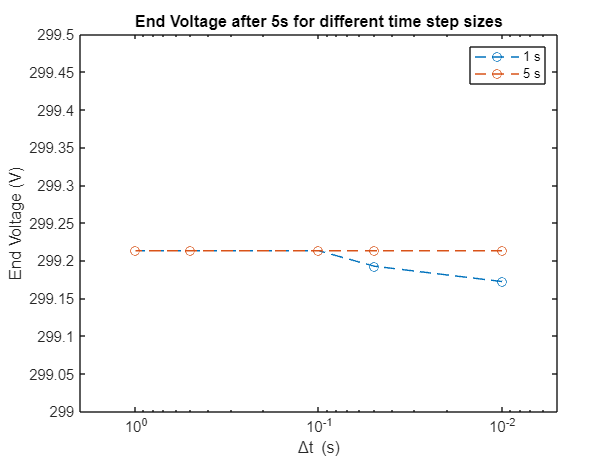


tss = [0.01 , 0.05 , 0.1 , 0.5, 1];

voltage_tss = [299.17202254808075 , (299.17202254808075+299.2128001491582)/2 , 299.2128001491582 , 299.2128001491582 , 299.2128001491582 ;
    299.2129872 ,299.2129872 , 299.2129872	299.2129872	299.2129872];

h2_out_tss = [0.3203629189954555 , (0.3203629189954555+0.31477136893117375)/2 ,  0.31677136893117375 , 0.31677136893117375 , 0.31677136893117375 ;
    0.314684065, 0.314684065 , 0.314684065	0.314684065	0.314684065];

semilogx(tss, voltage_tss, "o--")
xlim([0.005, 2])
ylim([299,299.5])
set(gca, 'XDir', 'reverse')
legend("1 s" , "5 s")
xlabel("\Deltat (s)")
ylabel("End Voltage (V)")
title("End Voltage after 5s for different time step sizes")

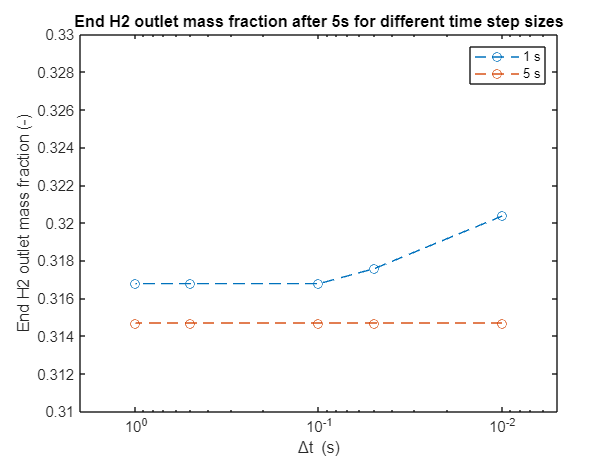


semilogx(tss, h2_out_tss, "o--")
xlim([0.005, 2])
ylim([0.31,0.33])
set(gca, 'XDir', 'reverse')
legend("1 s" , "5 s")
xlabel("\Deltat (s)")
ylabel("End H2 outlet mass fraction (-)")
title("End H2 outlet mass fraction after 5s for different time step sizes")